# Create and Customize Swarm Charts

Swarm scatter charts are scatter plots with the points offset (jittered) in the x-dimension.

### Read Bicycle Data

We will use *bicycleData.mat* to demonstrate how to create and customize swarm charts. The MAT file contains bicycle traffic data over a period of time. First, use a helper function to load the data, process it and obtain variables that can be plotted.

[day,bikeCount,hourOfDay] = readBicycleData;

### Basic Swarm Chart

View the distribution of bicycle traffic according to the day of the week.

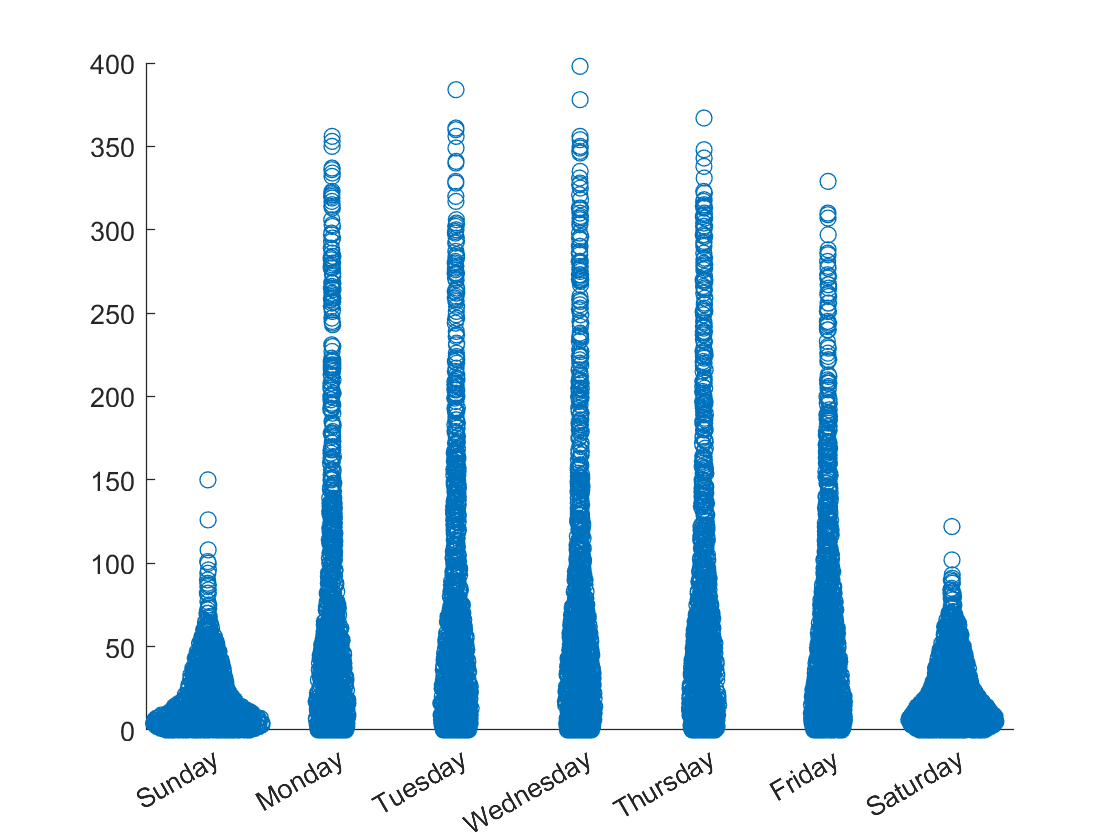

swarmchart(day,bikeCount);

## Customization

### Change Marker Properties

To specify the marker size and whether the marker is filled, use the 3rd and 4th input arguments to `swarmchart`.

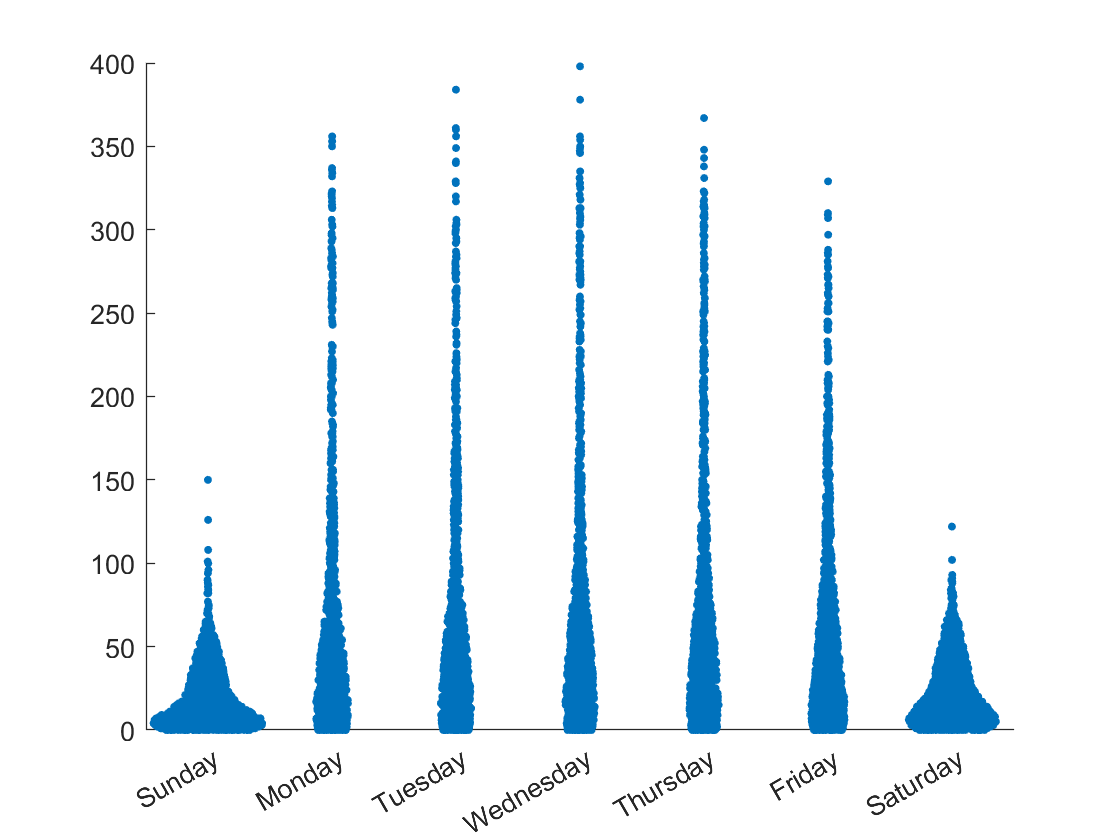

markerSize = 9;

s = swarmchart(day,bikeCount,...
    markerSize,...  % Specify marker size
    "filled");      % Specify marker as filled

### Display Markers with Varied Color

The *c* input argument can be used to create varying marker colors. In this instance, the hour variable can be used to see how bicycle traffic changes by the hour on each day. The chart shows that traffic is heaviest in the morning and in the evening. The colorbar shows how colors correspond to the hour in the day.

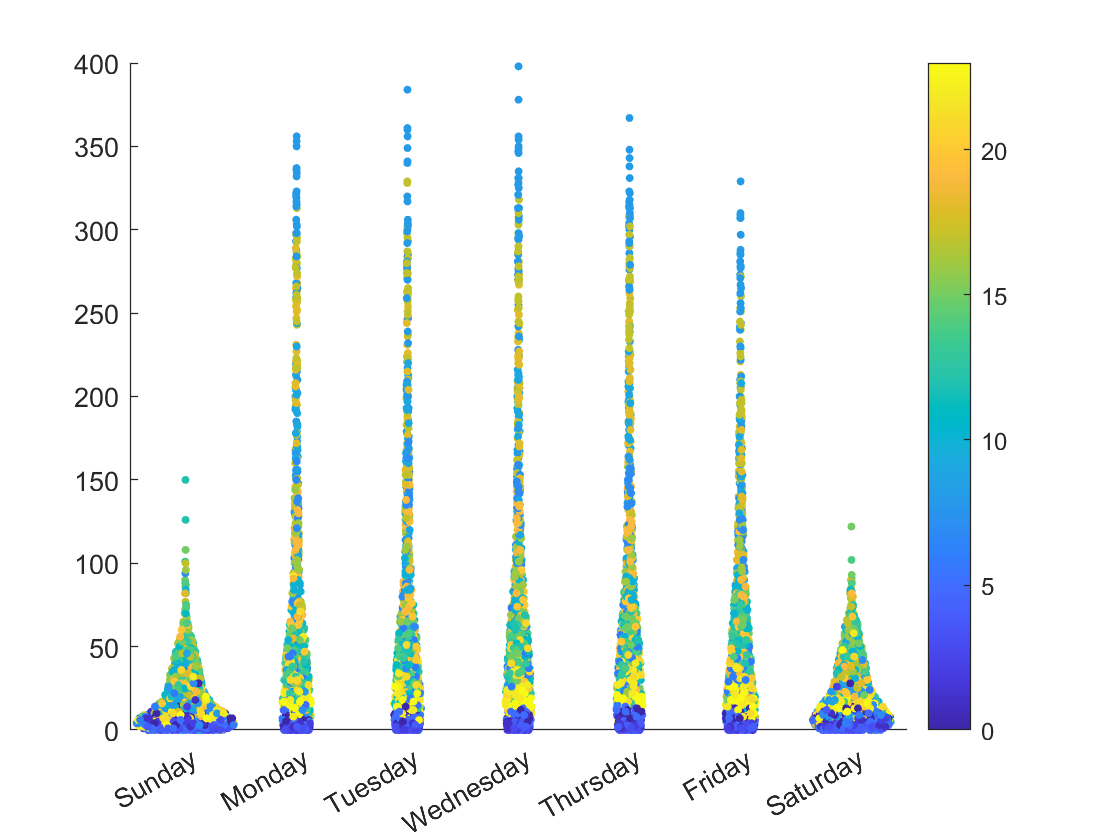

figure
s1 = swarmchart(day,bikeCount,...
    markerSize,...  
    hourOfDay,...   % Specify variable used to determine marker colors
    "filled");      
colorbar()     % Use colorbar to see how colors correspond to hours in the day

### Change Jitter Type and Width

If the varying widths of the clusters on each day are undesired, use the jitter properties to create uniform distributions and limit the width to maintain the distinction between each day. Add a label to the color bar for clarity.

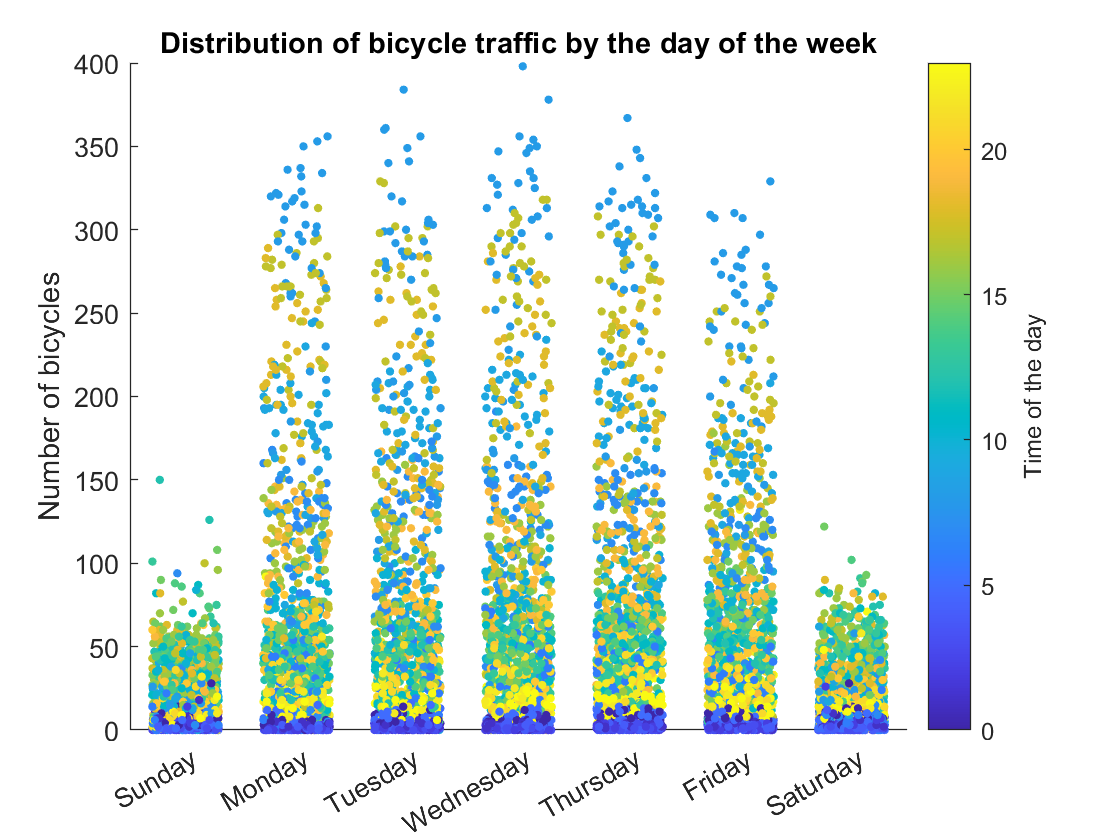

XJitterType = "rand";
XJitterWidth = 0.6;

s2 = swarmchart(day,bikeCount,10,hourOfDay,"filled",...
    "XJitter",XJitterType,...       % Specify the jitter type
    "XJitterWidth",XJitterWidth);   % Specify the jitter width        
title("Distribution of bicycle traffic by the day of the week")
c = colorbar();
ylabel(c, "Time of the day");
ylabel("Number of bicycles")

## **Additional Information**

### **Get All Scatter Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Scatter object, uncomment the following code. View or modify these properties using dot notation.

% get(s)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[swarmchart](https://www.mathworks.com/help/matlab/ref/swarmchart.html)

### Helper Functions

This helper function reads in bicycle data and processes the data to generate three variables:

- bikeCount - Total number of bicycles recorded in a given hour on a given day

- hour - Hour of the day corresponding to each recorded number of bicycles

- day - Day of the week corresponding to each recorded number of bicycles

function [day, bikeCount, hourx] = readBicycleData()
    load bicycleData.mat bicycleData;
    daynames = ["Sunday" "Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday"];
    day = categorical(bicycleData.Day,daynames);
    bikeCount = bicycleData.Total;
    hourx = hour(bicycleData.Timestamp);
end

Copyright (c) 2021, The MathWorks, Inc.